# LAB 2: Processat linial d'Imatges I

Tenim diverses tèniques per procesar imatges i obtenir dades:

### Histograma d'imatges

Representació del valors i el seu nombre de píxels a l'imatge. Exemple per una imatge blanc i negre:

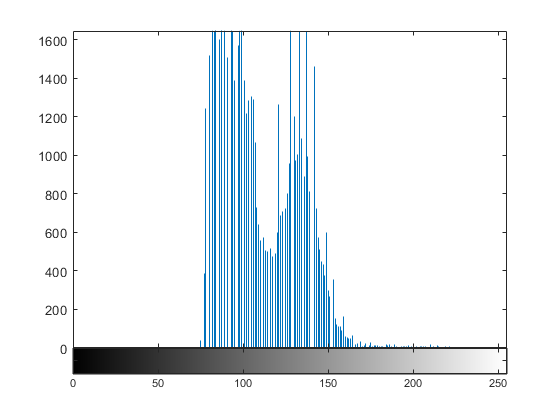

I = imread('pout.tif');
imhist(I)

## Técnicas de millora del contrast

Aqui trobem diverses maneres de millorar el contrast. Tambe serveix per imatges en color.

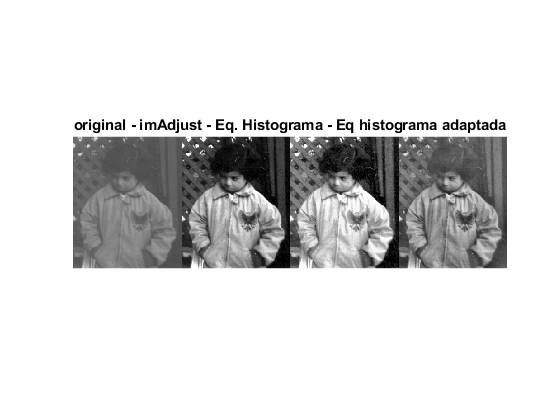

pout = imread('pout.tif'); 
pout_imadjust = imadjust(pout); %el 1% se satura a intensidades bajas y altas
pout_histeq = histeq(pout); %equalización de histograma
pout_adapthisteq = adapthisteq(pout); %equalizacion histo adaptada
montage({pout,pout_imadjust,pout_histeq,pout_adapthisteq},'Size',[1 4]) 
title("original - imAdjust - Eq. Histograma - Eq histograma adaptada");

## Operacions de punt

Es poden aplicar funcions de transformació píxel a píxel, el píxel resultant nomes depen del píxel original:

%B = arrayfun(@(x) mean(x.f1), A);

Les mes habituals son:

- Thresholding : Separan la forma del fondo (binaritzen) mirant l'histograma.

- Adaptative Thresholding : Usant alguna funcio estadística podem ajusta el TH.

- Log : Redueix el contrast a les regions brillants.

- Exponential : Millora el contrast a les regions brillants.

- Suma/ Resta: Aporta lluminositat/ Treu lluminositat

- Multiplicar: Incrementa el contrast.

## Transformacions geomètriques

Permeten eliminar les distorsions geomètriques produïdes en capturar l'imatge.

Un pixel (x,y) es "mou" a un nou (x',y'). Les operacions mes comunes son: Escalar, Rotar, Reflectar, Traslladar

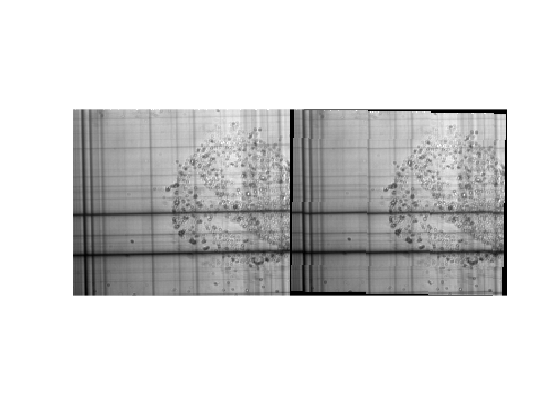

im = fitsread('solarspectra.fts');
im = rescale(im);
x = imrotate(im, -1);
montage({im, x})

%imtranslate(...)
%imresize(...)

## Operacions aritmètiques entre imatges

Es poden definir operacions entre imatges, per tal de trobar informació interesant. El problema es si el resultat d'operar un píxel contra l'altre tenim un resultat fora de rang, es poden optar per diferents estrategies.

# LAB 3 : Filtrat d'imatges - Processat linial d'Imatges II

Fins ara, teniam filtres locals (el nou valor del píxel es funció del píxel original),es pot ampliar a filtres a partir de productes de convolució, on el nou valor depen dels píxels veïns, ponderant la contribució de cada píxel veí al pixel resultant. 

Aquesta operació es defineix com el producte de convolució; es poden tenir problemes amb les vores, podem optar per inventar valors dels píxels, considerem la imatge cíclica, no fem cálcul alla o no es pot ...

Existeixen diverses aplicacions, segons el filtre que apliquem:

### Suavitzat de la imatge

Filtres lineals:

- Filtre mitjana : Es suavitzen contorns i s'elimina el soroll de la imatge, es perden detalls petits.

- Filtre gaussià (+ popular): La influència dels píxels veïns disminueix amb la distancia al centre.

Filtres no lineals

- Filtre mediana : Redueix el *blurring* que produeix el filtre mitjana. S'ordenan els píxels d'un entorn i el valor mitj s'assigna al píxel central. Existeixen diverses variacions (percentil, k-nearest, sigma,...)

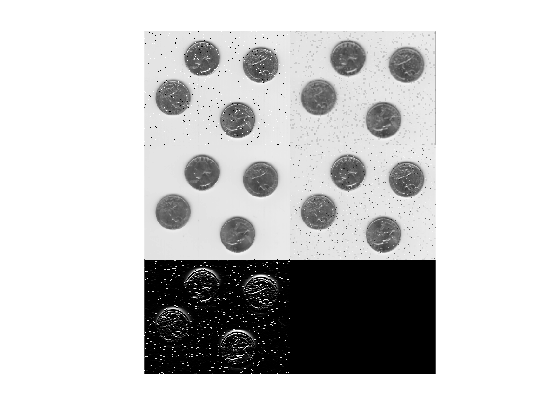

%imatge amb soroll:
I = imread('eight.tif');
I = imnoise(I, "salt & pepper", 0.02);

%fspecial crea un filtre:
h_avg = fspecial('average', [3,3]); %filtre mitjana, de talla 3x3
h_soble = fspecial('sobel'); %filtre mitjana, de talla 3x3
%imfilter aplica el filtre
I_avgfilt = imfilter(I, h_avg);
I_sobel = imfilter(I, h_soble);
I_medfilt = medfilt2(I); %hi ha filtres que tenen la seva funció propia.
I_gauss = imgaussfilt(I);
montage({I, I_avgfilt, I_medfilt, I_gauss, I_sobel})

### Filtres per obtenir contorns

Un contorn es un canvi local i significatiu en la intensitat. En imatges "reals" es complicat trobar el contorn degut al soroll i a que el canvi d'intensitat s'esten a mes d'un pixel. Per tant, cal 

- un proces de detecció de vores  

- realçat de vores 

- recol·lecció de pixels per trobar el contorn (suma de vores de la imatge).

L'operació gradient indica el canvi d'una funció (equivalent 2d a 1a derivada). Unes implementacions d'aquets gradients estan en els filtres: 

- Prewitt

- Roberts

- Sobel (té ponderació)

Podem derivar un altre cop i buscar pics en una 2a derivada:

- Laplacian

- Laplacian of Gaussian LoG

Per tant, per obtenir contorns:

- Filtrar l'imatge (els gradients son molt sensibles al soroll)

- Realçat, per enfatizar els píxels on hi ha una variació significativa.

- Detecció

- Localització 

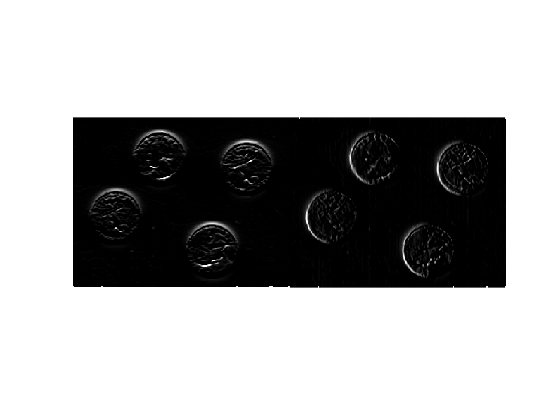

%filtro prewitt que enfatiza los bordes horizontales, per enfatizar els
%verticals s'ha de transposar
h_prew_hori = fspecial ("prewitt");
h_prew_vert = transpose(h_prew_hori);
I_prew_h = imfilter(I_medfilt, h_prew_hori);
I_prew_v = imfilter(I_medfilt, h_prew_vert);
montage({I_prew_h, I_prew_v})

A matlab, l'operació edge retorna una imatge binaria con los bordes (utilitza sobel).

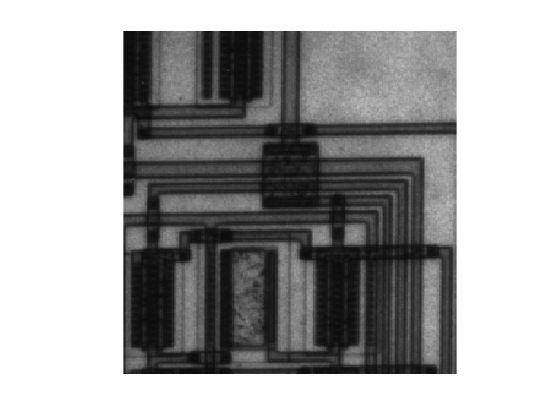

I_circuito = imread('circuit.tif'); imshow(I_circuito)

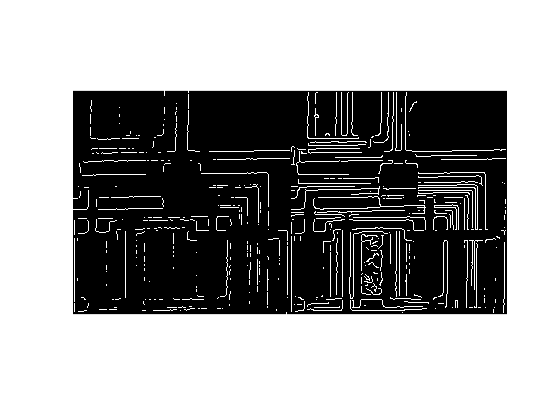

BW1 = edge(I_circuito, 'Prewitt');
BW2 = edge(I_circuito, 'Canny');
montage({BW1, BW2});